t = 1:1830;                     %Länge des Fahrzyklus in s
t = t';                         %Transponierte der Zeitvektors
spd = Position.speed;           %Auslesen der Geschw. aus Matfile 
grade = Orientation.Z;          %Auslesen der Steigung aus Matfile

gradeneu = grade(1:10:18300);
grade1 = interp1(grade, t);
d1 = designfilt('lowpassfir') %spr = t; 20-30Hz

designfilt('lowpassfir','PassbandFrequency',20,'StopbandFrequency',30,'PassbandRipple',1,'StopbandAttenuation',60,'SampleRate',1830);


d1 =  digitalFilter with properties:

           Coefficients: [5.5232e-04 1.2656e-04 1.3994e-04 1.5341e-04 1.6689e-04 1.8023e-04 1.9336e-04 2.0610e-04 2.1835e-04 2.2991e-04 2.4066e-04 2.5035e-04 2.5883e-04 2.6584e-04 2.7123e-04 2.7475e-04 2.7632e-04 2.7570e-04 2.7288e-04 2.6760e-04 … ]

   Specifications:
      FrequencyResponse: 'lowpass'
        ImpulseResponse: 'fir'
             SampleRate: 1830
    StopbandAttenuation: 60
      PassbandFrequency: 20
      StopbandFrequency: 30
         PassbandRipple: 1
           DesignMethod: 'equiripple'

 Use fvtool to visualize filter
 Use designfilt to edit filter
 Use filter to filter data


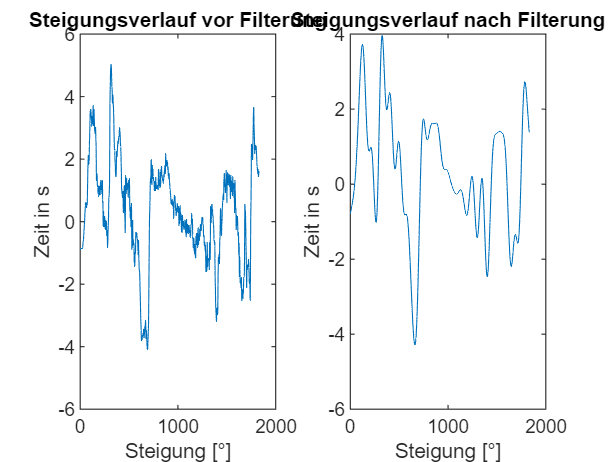

%d2 = designfilt('lowpassfir')
xdot1 = filtfilt(d1, spd);


y = filtfilt(d1, grade1);



figure 
subplot(1,2,1)
plot(grade1)
title('Steigungsverlauf vor Filterung')
xlabel('Steigung [°]')
ylabel('Zeit in s')
subplot(1,2,2)
plot(y)
title('Steigungsverlauf nach Filterung')
xlabel('Steigung [°]')
ylabel('Zeit in s')

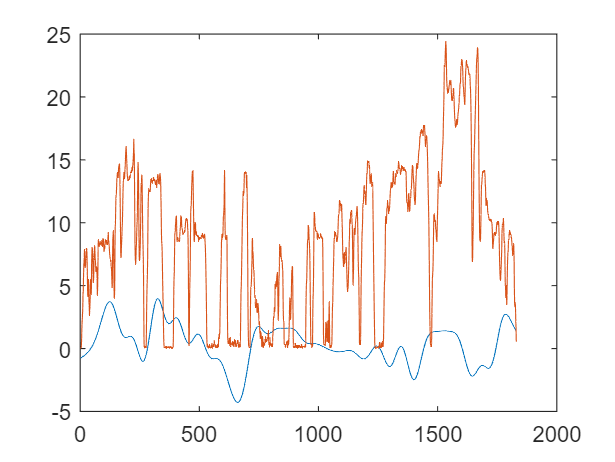



figure 
plot(y)
hold on
plot(spd)

myCycle = [t,spd];
myGrade = [t, y]; 